# Oefening 4.18

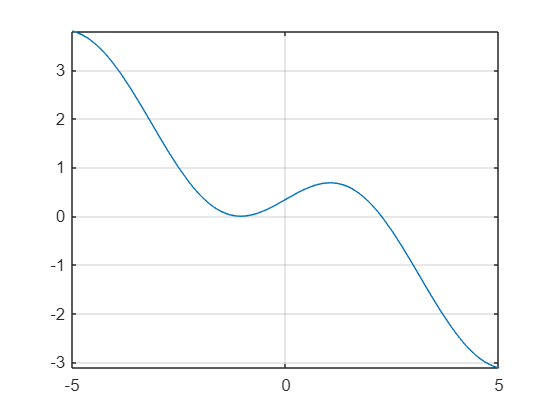


clear all; close all; clc; format long

g = @(x) sin(x) -x/2 -pi/6 + sqrt(3)/2;
fplot(g)
grid on

a = -4;
b = 4;
tol = 10^-10;
nmax = 100;
x0 = -pi/2;
res_1 = bisection(g,a,b,nmax,tol, false);

toleration: 100
Iterations: 1
Theory?: 0


res_2 = newton(g,x0,tol)

-1.047206 is het nulpunt


res_2 =                    0  -1.570796326794897
   1.000000000000000  -1.315146743627720
   2.000000000000000  -1.183631832053614
   3.000000000000000  -1.116174561731184
   4.000000000000000  -1.081897101040887
   5.000000000000000  -1.064602959203221
   6.000000000000000  -1.055914539391675
   7.000000000000000  -1.051559664465138
   8.000000000000000  -1.049379518712337
   9.000000000000000  -1.048288763440561


res_3 = newton_adapt(g,x0,tol)

-1.047206 is het nulpunt


res_3 =                    0  -1.570796326794897
   1.000000000000000  -1.315146743627720
   2.000000000000000  -1.183631832053614
   3.000000000000000  -1.116174561731184
   4.000000000000000  -1.081897101040887
   5.000000000000000  -1.064602959203221
   6.000000000000000  -1.055914539391675
   7.000000000000000  -1.051559664465138
   8.000000000000000  -1.049379518712337
   9.000000000000000  -1.048288763440561


## Oefening 4.19


clear all, close all, clc

fun = @(x) x^3 - 5*x + 3;
options = optimoptions('fsolve','Display','off');
theo_value = fsolve(fun,1,options); 

iter_bisectie = bisectie(fun,1,2,10^-10);

1.834243 is een nulpunt


iter_newton = newton(fun,2,10^-10);

1.834243 is het nulpunt


iter_secant = secant(fun,1,2,10^-10);

1.834243 is het nulpunt


iter_newton_adapt = newton_adapt(fun,2,10^-10);

1.834243 is het nulpunt


iter_cheby = cheby(fun,2,10^-10);

1.834243 is het nulpunt


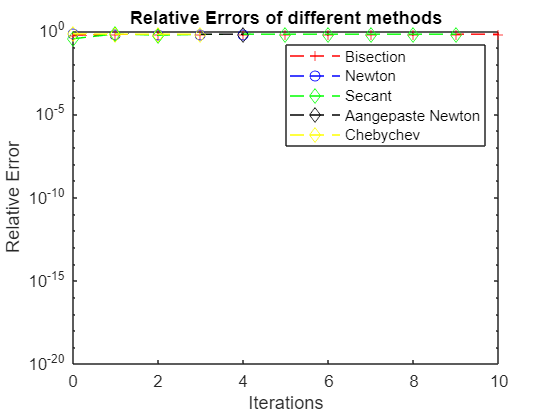

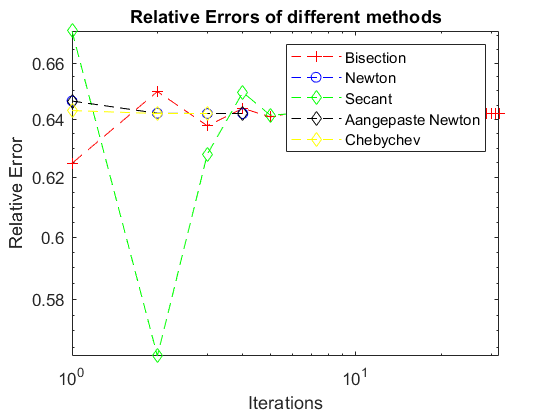


abs_err_bisectie = abs(theo_value - iter_bisectie(:,2));
rel_err_bisectie = abs_err_bisectie./iter_bisectie(:,2);
abs_err_newton = abs(theo_value - iter_newton(:,2));
rel_err_newton = abs_err_newton./iter_newton(:,2);
abs_err_secant = abs(theo_value - iter_secant(:,2));
rel_err_secant = abs_err_secant./iter_secant(:,2);
abs_err_newton_adapt = abs(theo_value - iter_newton_adapt(:,2));
rel_err_newton_adapt = abs_err_newton_adapt./iter_newton_adapt(:,2);
abs_err_cheby = abs(theo_value - iter_cheby(:,2));
rel_err_cheby = abs_err_cheby./iter_cheby(:,2);


figure();
semilogy(iter_bisectie(:,1),rel_err_bisectie,'r+--',iter_newton(:,1),rel_err_newton,'bo--',iter_secant(:,1),rel_err_secant,'gd--',iter_newton_adapt(:,1),rel_err_newton_adapt,'kd--',iter_cheby(:,1),rel_err_cheby,'yd--')
%axis([0 10 10^-20 1])
title('Relative Errors of different methods'); xlabel('Iterations'); ylabel('Relative Error')
legend('Bisection','Newton','Secant','Aangepaste Newton','Chebychev')

## 4.22

clear all, close all, clc

fun = @(x) 4*x^4 - 5*x - 3;
options = optimoptions('fsolve','Display','off');
theo_value = fsolve(fun,1,options); 

iter_bisectie = bisectie(fun,1,2,10^-10);

1.229779 is een nulpunt


iter_newton = newton(fun,2,10^-10);

1.229779 is het nulpunt


iter_secant = secant(fun,1,2,10^-10);

1.229779 is het nulpunt


iter_newton_adapt = newton_adapt(fun,2,10^-10);

1.229779 is het nulpunt


iter_cheby = cheby(fun,2,10^-10);

1.229779 is het nulpunt


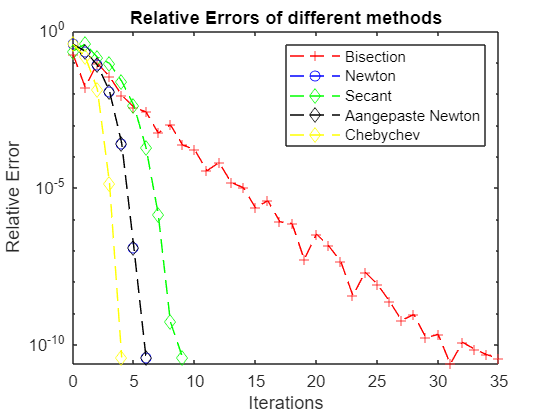


abs_err_bisectie = abs(theo_value - iter_bisectie(:,2));
rel_err_bisectie = abs_err_bisectie./iter_bisectie(:,2);
abs_err_newton = abs(theo_value - iter_newton(:,2));
rel_err_newton = abs_err_newton./iter_newton(:,2);
abs_err_secant = abs(theo_value - iter_secant(:,2));
rel_err_secant = abs_err_secant./iter_secant(:,2);
abs_err_newton_adapt = abs(theo_value - iter_newton_adapt(:,2));
rel_err_newton_adapt = abs_err_newton_adapt./iter_newton_adapt(:,2);
abs_err_cheby = abs(theo_value - iter_cheby(:,2));
rel_err_cheby = abs_err_cheby./iter_cheby(:,2);


figure();
semilogy(iter_bisectie(:,1),rel_err_bisectie,'r+--',iter_newton(:,1),rel_err_newton,'bo--',iter_secant(:,1),rel_err_secant,'gd--',iter_newton_adapt(:,1),rel_err_newton_adapt,'kd--',iter_cheby(:,1),rel_err_cheby,'yd--')
%axis([0 10 10^-20 1])
title('Relative Errors of different methods'); xlabel('Iterations'); ylabel('Relative Error')
legend('Bisection','Newton','Secant','Aangepaste Newton','Chebychev')

## Theorie oef 4.7


f = @(x,p) (x^2-1)^p * log(x);

for p = [2 4 6]
    newton_adapt(@(x) f(x,p), 0.8,1e-6)
end



These functions return iteration arrays and are therefore a bit different.

function [iterations_array] = bisectie(f,a,b,tol)
i = 0;
x = [];
stopcriterium = 0;
    while stopcriterium == 0
        i = i+1;
        if abs(f(a)) < tol
            stopcriterium = 1;
            fprintf('%f is een nulpunt\n',a)
        elseif abs(f(b)) < tol
            stopcriterium = 1;
            fprintf('%f is een nulpunt\n',b)
        elseif f(a)*f(b) < 0
            x(i) = (a + b)/2;
            if abs(f(x(i))) < tol
                stopcriterium = 1;
                fprintf('%f is een nulpunt\n',x(i))
            elseif f(a)*f(x(i)) < 0
                b = x(i);
                continue
            elseif f(b)*f(x(i)) < 0
                a = x(i);
                continue
            end
        else
            error('Kies de waarden a en b zodanig dat hun functiewaarden een tegengesteld teken hebben')
        end
    end
    iterations_array = zeros(length(x),2);
    iterations_array(:,1) = 0:length(x)-1;
    iterations_array(:,2) = x';
end
function [iterations_array] = newton(f,x0,tol)
i = 0;
x = [x0];
syms y
df1 = matlabFunction( diff(f(y)) );
g = matlabFunction( y - f(y)/df1(y) );
stopcriterium = 0;
    while stopcriterium == 0
        i = i+1;
        if abs(df1(x(i))) < tol
            error(sprintf('De waarde %f in de iteratie geeft nul voor de eerste afgeleide. Je mag niet delen door nul.',x(i)))
        elseif abs(f(x(i))) < tol
            stopcriterium = 1;
            fprintf('%f is het nulpunt\n',x(i))
        else
            x(i+1) = x(i) - f(x(i))/df1(x(i));
            continue
        end
    end
    iterations_array = zeros(length(x),2);
    iterations_array(:,1) = 0:length(x)-1;
    iterations_array(:,2) = x';
end

%WRONG idk 
function [iterations_array] = newton_adapt(f,x0,tol)
i = 0;
x = [x0];
syms y
df1 = matlabFunction( diff(f(y)) );
g = matlabFunction( y - 2*f(y)/df1(y) );
stopcriterium = 0;
    while stopcriterium == 0
        i = i+1;
        if abs(df1(x(i))) < tol
            error(sprintf('De waarde %f in de iteratie geeft nul voor de eerste afgeleide. Je mag niet delen door nul.',x(i)))
        elseif abs(f(x(i))) < tol
            stopcriterium = 1;
            fprintf('%f is het nulpunt\n',x(i))
        else
            x(i+1) = x(i) - f(x(i))/df1(x(i));
            continue
        end
    end
    iterations_array = x';
end

function [iterations_array] = secant(f,x0,x1,tol)
i = 1;
x = [x0,x1];
syms y
df1 = matlabFunction( diff(f(y)) );
g = matlabFunction( y - f(y)/df1(y) );
stopcriterium = 0;
    if abs(f(x0)) < tol
        stopcriterium = 1;
        fprintf('%f is het nulpunt\n',x0)
    else
        while stopcriterium == 0
            i = i+1;
           if abs(f(x(i))) < tol
                stopcriterium = 1;
                fprintf('%f is het nulpunt\n',x(i))
            else
                sec = (f(x(i))-f(x(i-1)))/(x(i)-x(i-1));
                x(i+1) = x(i) - f(x(i))/sec;
                continue
            end
        end
    end
    iterations_array = zeros(length(x),2);
    iterations_array(:,1) = 0:length(x)-1;
    iterations_array(:,2) = x';
end


function [iterations_array] = cheby(f,x0,tol)
i = 0;
x = [x0];
syms y
df = matlabFunction(diff(f(y),1));
d2f = matlabFunction(diff(f(y),2));
stopcriterium = 0;
    while stopcriterium == 0
        i = i+1;
        if abs(df(x(i))) < tol
            error(sprintf('De waarde %f in de iteratie geeft nul voor de eerste afgeleide. Je mag niet delen door nul.',x(i)))
        elseif abs(f(x(i))) < tol
            stopcriterium = 1;
            fprintf('%f is het nulpunt\n',x(i))
        else
            x(i+1) = x(i) - f(x(i))/df(x(i)) - 0.5*(f(x(i))/df(x(i)))^2*d2f(x(i))/df(x(i));
            continue
        end
    end
    iterations_array = zeros(length(x),2);
    iterations_array(:,1) = 0:length(x)-1;
    iterations_array(:,2) = x';
end